# EJERCICIOS DETERMINISTAS

## Ejercicio 1 : Crecimiento de Pablaciones 

Supongamos que la población del Lince ibérico crece a razón de un 13% anual. En el año 2002 se  reintrodujeron 94 ejemplares en la península ibérica para intentar evitar su extinción. Hagamos que sea  la población inicial de Linces y la población después de n años:


$$p_{n+1} =p_n +0\ldotp 13p_n ={1\ldotp 13p}_n$$


**Definición del Problema:**

**Variables :  **


$$p=\mathrm{número}\;\mathrm{de}\;\mathrm{linces}$$



$$n=\mathrm{tiempo}\;\left(\mathrm{años}\right)$$


p = 94; 
n = 2002; 
razon = 1.13; 
fin = 2015 ; % Año que se quiere calcular la cantidad de linces.
crecimiento = (p);
i = 1;

crecimiento = Crecimiento (p, n, razon, fin, crecimiento, i)

crecimiento =    94.0000  106.2200  120.0286  135.6323  153.2645  173.1889  195.7035  221.1449  249.8938  282.3799  319.0893  360.5709  407.4452  460.4130


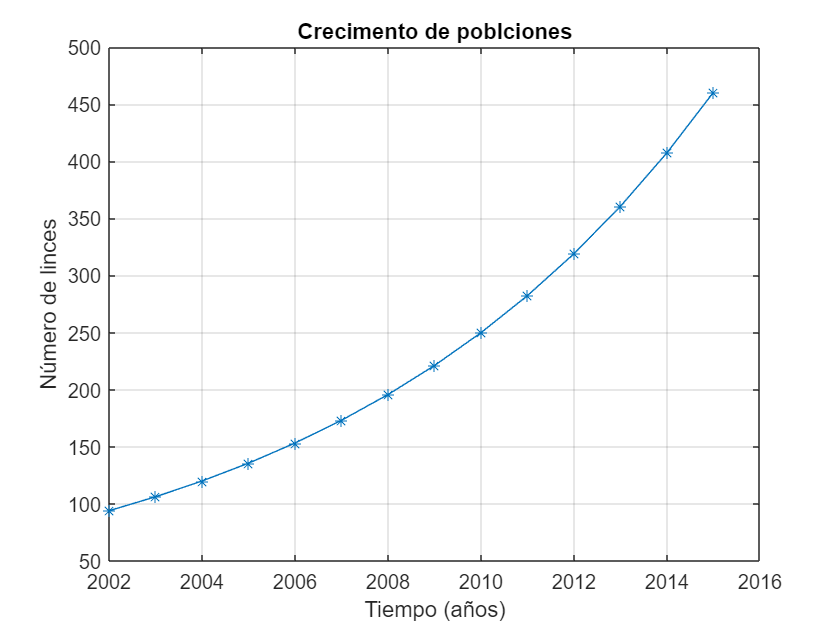


plot(n:fin,crecimiento,'- *')
grid on
title('Crecimento de poblciones')
xlabel('Tiempo (años)')
ylabel('Número de linces')

## Ejercicio 2 : Ley de enfriamiento de Newton 

Supongamos que una taza de café, inicialmente a una temperatura de 65ºC se coloca en una habitación que  se mantiene a una temperatura constante de 20ºC. Después de 1 minuto, el café se ha enfriado a 60ºC.  Si necesitamos encontrar la temperatura del café después de 15 minutos, utilizaremos la ley de Newton  del enfriamiento, que establece que la tasa de cambio de la temperatura de un objeto es proporcional a la  diferencia entre su propia temperatura y la temperatura ambiente (es decir, la temperatura de su entorno).  Matemáticamente, esto significa,


$$t_{n+1} -t_n =k\;\left(S-t_n \right)$$


donde $t_n$ es la temperatura del café después de $n$ minutos, $S$ es la temperatura de la habitación y $k\;$es la  constante de proporcionalidad. Tomar $k=\frac{1}{8}$ .

**a)** Definir la ecuación en diferencias que representa el proceso de enfriamiento del café tomando como guía la ley de enfriamiento de Newton. 

A tener el cuenta el nombre de las siguientes variables:

- T(n) = temperatura en el minuto n.

- k = constante de proporcionalidad.

- a = temperatura ambiente (en este caso constante = 20º).

**b) **Determinar el valor de la constante de proporcionalidad k teniendo en cuenta la información del problema sobre los cambios en el primer minuto. 

**c) **Realizar el diagrama de flujo que representa la simulación del proceso de enfriamiento del café.

**d)** Realizar un programa en Matlab que devuelva:

- Temperatura del café después de 15 minutos en la habitación. 

- Un gráfico de la evolución de la temperatura del café durante los 15 minutos que el café permanece en la habitación. 

**e) **Estudiar la estabilidad del sistema y, en caso de que sea estable, calcular el punto de equilibrio.

**Solución a)**

$\Delta$Tn =(T1 - a) k * Tn+1 

**Solución b)**

Tinicio = 65; % temperatura inicial 
Tfin = 60; % temperatura final 
a = 20; % Temperatura ambiente

k = - ( Tinicio - Tfin) / (Tinicio - a); % Constante de proporcionalidad

fprintf('La constante de proporcionalidad es : %.4f', k)

La constante de proporcionalidad es : -0.1111

**Solución c)**

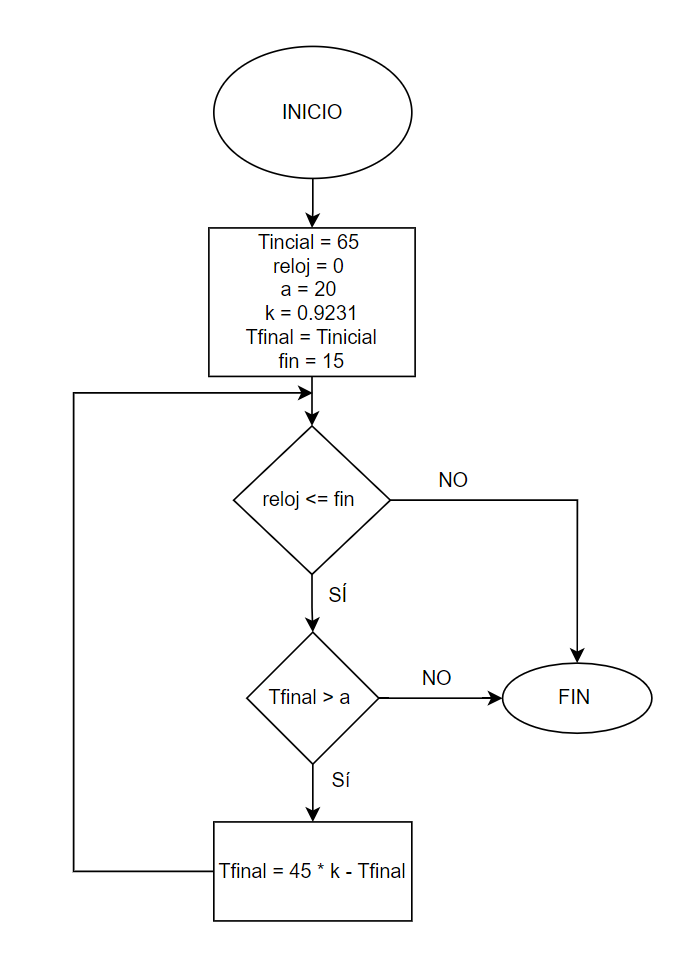

**Solución d)**

reloj = 1 ; 
fin = 15;
Tfin = Tinicio;

temperatura = (Tinicio);
i = 1;
% Rutina de parada 
while reloj <= fin 

    % Rutina de tiempo
    reloj = reloj + 1;

    if Tfin > a

    % Rutina de evento 
        Tfin = (Tinicio - a) * k + Tfin;
        Tinicio = Tfin;
        temperatura(i) = Tfin;
        i = i + 1;
    else
        fprintf('La temperta es igual a la temperatura ambiente')
        break
    end

end
fprintf('La temperatura en el minuto 15 es : %.4f', temperatura(i-1))

La temperatura en el minuto 15 es : 27.6900

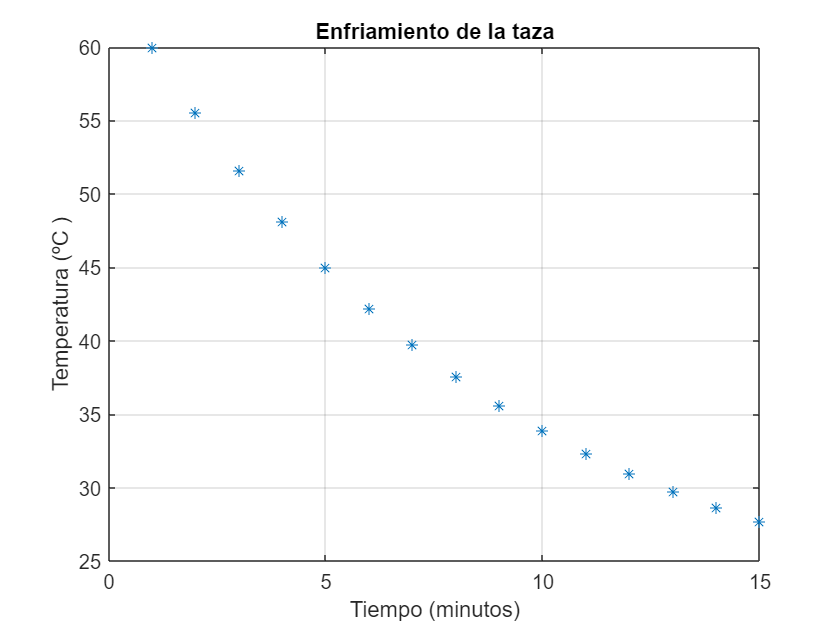

plot(1:15,temperatura,'*')
grid on 
title ('Enfriamiento de la taza');
xlabel( 'Tiempo (minutos)');
ylabel('Temperatura (ºC )');

**Solución e)**

% Rutina de parada 
fin = inf;
while reloj <= fin 

    % Rutina de tiempo
    reloj = reloj + 1;

    if Tfin > a

    % Rutina de evento 
        Tfin = (Tinicio - a) * k + Tfin;
        Tinicio = Tfin;
        temperatura(i) = Tfin;
        i = i + 1;
    else
        fprintf('La temperta es igual a la temperatura ambiente')
        break
    end
    T1 = temperatura(i-2);
    T1 = round(T1, 4);
    T2 = temperatura(i-1);
    T2 = round(T2, 4);
    if T1 == T2
        fprintf('Estabilidad del sistema: %.4f', T1);
        break
    end

end

Estabilidad del sistema: 20.0006

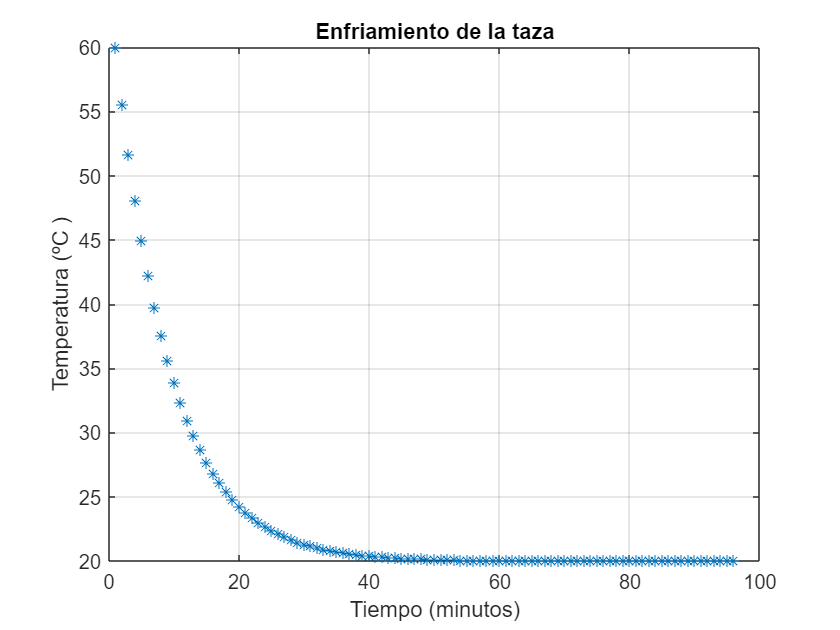


plot(1:(i-1),temperatura,'*')
grid on 
title ('Enfriamiento de la taza');
xlabel( 'Tiempo (minutos)');
ylabel('Temperatura (ºC )');


fprintf(['Como vemos en la gráfica la estabilidad del sistema es ' ...
    '( punto de equilibrio ): %.4f ºC y llegamos en el minuto %d'], T1, i)

Como vemos en la gráfica la estabilidad del sistema es ( punto de equilibrio ): 20.0006 ºC y llegamos en el minuto 97

## Ejercicio 3 : Amortización de un préstamo (1)

Cálcular el capital que queda por amortizar de un préstamo de 15000 euros al cabo de 100 meses, si se ha  establecido una cuota de 200 euros/mes a un interés mensual del 1% (12% anual).

**Definición del Problema:**

**Variables :  **

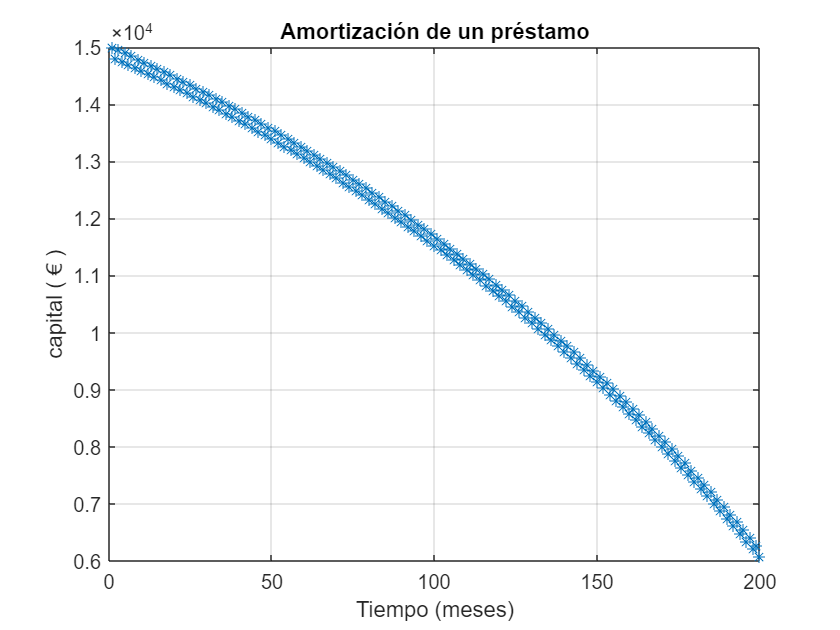

clc, clear, clf

prestamo = 15000; 
interes = 0.01;
plazo = 100; % meses
cuota = 200; 
n = 1;
capital = prestamo - cuota;
seguimiento = [prestamo, capital];
i = 2;

while n < plazo

    capital = capital * interes + capital;
    i = i + 1;
    seguimiento(i) = capital;
    capital = capital - cuota;
    n = n + 1;
    i = i + 1;
    seguimiento(i) = capital; 
end
plot(1: i, seguimiento,'*')
grid on
title('Amortización de un préstamo')
xlabel('Tiempo (meses)')
ylabel('capital ( € )')

fprintf('El capital que le queda por amortizar despues de %d meses es: %.4f', plazo, capital)

El capital que le queda por amortizar despues de 100 meses es: 6074.2258

## Ejercicio 4 : Amortización de un préstamo (2) 

Considerando la amortización del préstamo del ejercicio anterior, realizar el cálculo del balance a final de mes  calculado según:


$$b\left(k\right)=b\left(k+1\right)+\int_{T\left(k-1\right)}^{T\left(k\right)} \left\lbrack i\;b\left(k-1\right)-p\right\rbrack \;\mathrm{dt}$$


## Ejercicio 5 : Ecuación en diferencias 

Estudiar la ecuación en diferencias:


$$y\left(k+2\right)\;+\;y\left(k\right)=0,\mathrm{siendo}\;y\;\left(0\right)=1\;\;e\;\;y\left(1\right)=0\;$$


## Funciones

### 1 .- Crecimiento 

function [crecimiento] = Crecimiento (p, n, razon, fin, crecimiento, i)

ans = -295485000


    while n < fin
        p = razon * p;
        i = i + 1;
        crecimiento(i) = p;
        n = n + 1;
    end

end
